wyO=readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\07-虚拟仪器\Data\Ex-7 原始实验数据 2-05-丁毅\测量伏安特性\50欧姆电阻.xlsx")
U_array = wyO(1, :);
I_array = wyO(2, :);

U = @(R, i) R*i
GridSearch.Var = [
    46 58 100000
];
[GridSearch, fig] = MyGridSearch(GridSearch, @(R) - GetError(@(i) U(R, i), U_array, I_array), 0);

stc = MyPlot(wyO(1, :), wyO(2, :));
stc.label.x.String = '$u$ (V)';
stc.label.y.String = '$i$ (A)';
stc.leg.String = '$i = \frac{u}{46.9808\ \Omega}$'
%MyExport_pdf_modal

test = @(R) GetError(@(i) U(R, i), x, y)
test(0)
test(20)
test(50)
R = 50
U(R, y) - x

iqO=readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\07-虚拟仪器\Data\Ex-7 原始实验数据 2-05-丁毅\测量伏安特性\1K欧姆电阻.xlsx")
U_array = iqO(1, :);
I_array = iqO(2, :);

U = @(R, i) R*i
GridSearch.Var = [
    995 1005 700000
];
[GridSearch, fig] = MyGridSearch(GridSearch, @(R) - GetError(@(i) U(R, i), U_array, I_array), 0);

stc = MyPlot(iqO(1, :), iqO(2, :));
stc.label.x.String = '$u$ (V)';
stc.label.y.String = '$i$ (A)';
stc.leg.String = '$i = \frac{u}{1000.7715\ \Omega}$'
%MyExport_pdf_modal

ZLerji=readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\07-虚拟仪器\Data\Ex-7 原始实验数据 2-05-丁毅\测量伏安特性\整流二极管.xlsx")
U_array = ZLerji(1, :);
I_array = ZLerji(2, :);

I = @(I_s, U_TH, u) I_s * (exp(u/U_TH) - 1) 
GridSearch.Var = [
    10^(-20) 10^(-19) 50
    0.001     0.050 100
];

[GridSearch, fig] = MyGridSearch(GridSearch, @(I_s, U_TH) - GetError_fu(@(u) I(I_s, U_TH, u), U_array, I_array), 0);

stc = MyPlot(ZLerji(1, :), ZLerji(2, :));
stc.label.x.String = '$u$ (V)';
stc.label.y.String = '$i$ (A)';
stc.leg.String = '$i$'
%MyExport_pdf_modal

I_s = 10^(-20)
U_TH = 0.020
GetError_fu(@(u) I(I_s, U_TH, u), U_array, I_array)
stc = MyPlot(ZLerji(1, :), I(I_s, U_TH, ZLerji(1, :)));

ZLerji=readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\07-虚拟仪器\Data\Ex-7 原始实验数据 2-05-丁毅\测量伏安特性\整流二极管.xlsx")

ZLerji =    -0.0026    0.0470    0.0966    0.1465    0.1964    0.2476    0.2966    0.3478    0.3977    0.4482    0.4988    0.5477    0.5970    0.6408    0.6752    0.6974    0.7119    0.7216    0.7306    0.7364    0.7419    0.7461    0.7506    0.7541    0.7580    0.7599    0.7625    0.7657    0.7667    0.7683    0.7715    0.7734    0.7754    0.7770    0.7776    0.7795    0.7805    0.7815    0.7831    0.7824    0.7828    0.7821    0.7831    0.7821    0.7821    0.7824    0.7815    0.7821    0.7821    0.7824
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0002    0.0005    0.0008    0.0012    0.0017    0.0021    0.0025    0.0030    0.0034    0.0039    0.0044    0.0048    0.0053    0.0058    0.0063    0.0067    0.0072    0.0077    0.0082    0.0086    0.0091    0.0096    0.0101    0.0106    0.0109    0.0108    0.0107    0.0107    0.0107    0.0107    0.0107    0.0106    0.0106    0.0106    0.0106

FGerji=readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\07-虚拟仪器\Data\Ex-7 原始实验数据 2-05-丁毅\测量伏安特性\发光二极管.xlsx")

FGerji =    -0.0013    0.0486    0.0992    0.1488    0.1987    0.2479    0.2982    0.3484    0.3989    0.4482    0.4984    0.5484    0.5983    0.6485    0.6994    0.7486    0.7979    0.8484    0.8990    0.9483    0.9982    1.0487    1.0980    1.1485    1.1978    1.2487    1.2983    1.3479    1.3981    1.4480    1.4992    1.5478    1.5968    1.6454    1.6911    1.7304    1.7600    1.7819    1.7990    1.8128    1.8251    1.8350    1.8437    1.8527    1.8614    1.8682    1.8743    1.8817    1.8875    1.8936
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0010    0.0013    0.0017    0.0021    0.0025    0.0029    0.0033    0.0038    0.0042    0.0046    0.0051

stc = MyPlot([ZLerji(1, :); FGerji(1, :)], [ZLerji(2, :); FGerji(2, :)]);
stc.label.x.String = '$u$ (V)';
stc.label.y.String = '$i$ (A)';
stc.leg.String = ["Rectifier Diode"; "Light Emitting Diode"]

stc = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


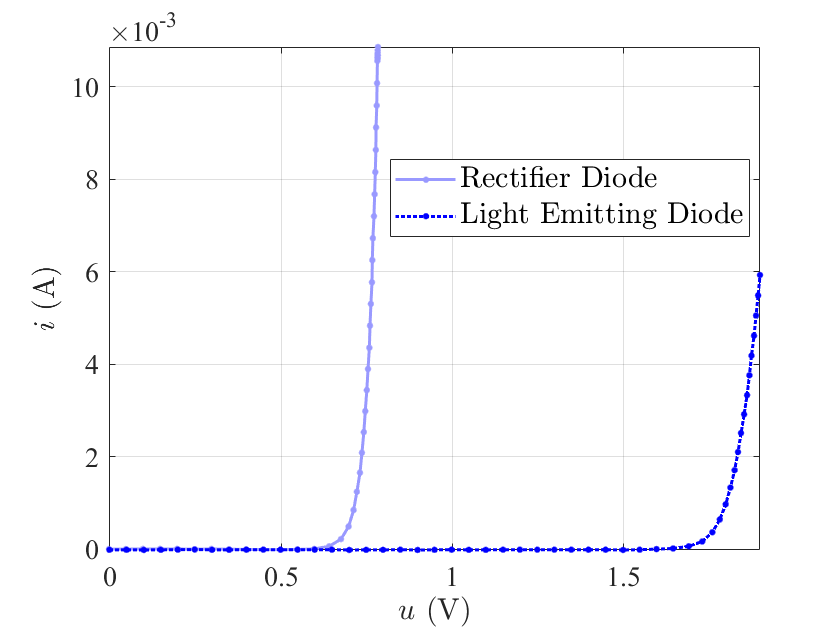

%MyExport_pdf_docked

ZLerji=readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\07-虚拟仪器\Data\Ex-7 原始实验数据 2-05-丁毅\测量伏安特性\整流二极管.xlsx")

ZLerji =    -0.0026    0.0470    0.0966    0.1465    0.1964    0.2476    0.2966    0.3478    0.3977    0.4482    0.4988    0.5477    0.5970    0.6408    0.6752    0.6974    0.7119    0.7216    0.7306    0.7364    0.7419    0.7461    0.7506    0.7541    0.7580    0.7599    0.7625    0.7657    0.7667    0.7683    0.7715    0.7734    0.7754    0.7770    0.7776    0.7795    0.7805    0.7815    0.7831    0.7824    0.7828    0.7821    0.7831    0.7821    0.7821    0.7824    0.7815    0.7821    0.7821    0.7824
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0001    0.0002    0.0005    0.0008    0.0012    0.0017    0.0021    0.0025    0.0030    0.0034    0.0039    0.0044    0.0048    0.0053    0.0058    0.0063    0.0067    0.0072    0.0077    0.0082    0.0086    0.0091    0.0096    0.0101    0.0106    0.0109    0.0108    0.0107    0.0107    0.0107    0.0107    0.0107    0.0106    0.0106    0.0106    0.0106

stc = MyPlot([ZLerji(1, :)], [ZLerji(2, :)]);
stc.label.x.String = '$u$ (V)';
stc.label.y.String = '$i$ (A)';
stc.leg.String = ["Rectifier Diode"]

stc = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


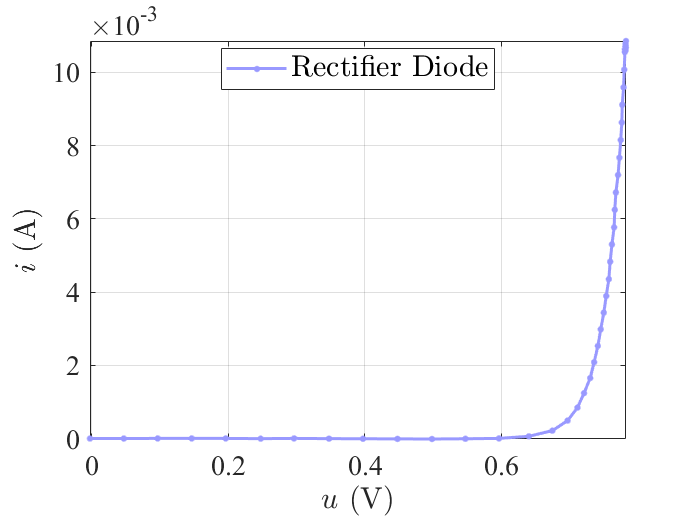

MyExport_pdf

FGerji=readmatrix("D:\a_RemoteRepo\GH.UCAS-BasicPhysicsExperiment\07-虚拟仪器\Data\Ex-7 原始实验数据 2-05-丁毅\测量伏安特性\发光二极管.xlsx")

FGerji =    -0.0013    0.0486    0.0992    0.1488    0.1987    0.2479    0.2982    0.3484    0.3989    0.4482    0.4984    0.5484    0.5983    0.6485    0.6994    0.7486    0.7979    0.8484    0.8990    0.9483    0.9982    1.0487    1.0980    1.1485    1.1978    1.2487    1.2983    1.3479    1.3981    1.4480    1.4992    1.5478    1.5968    1.6454    1.6911    1.7304    1.7600    1.7819    1.7990    1.8128    1.8251    1.8350    1.8437    1.8527    1.8614    1.8682    1.8743    1.8817    1.8875    1.8936
   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000    0.0001    0.0002    0.0004    0.0006    0.0010    0.0013    0.0017    0.0021    0.0025    0.0029    0.0033    0.0038    0.0042    0.0046    0.0051

stc = MyPlot([FGerji(1, :)], [FGerji(2, :)]);
stc.label.x.String = '$u$ (V)';
stc.label.y.String = '$i$ (A)';
stc.leg.String = ["Light Emitting Diode"]

stc = 包含以下字段的 struct :
      fig: [1×1 Figure]
     axes: [1×1 Axes]
     plot: [1×1 struct]
    label: [1×1 struct]
      leg: [1×1 Legend]


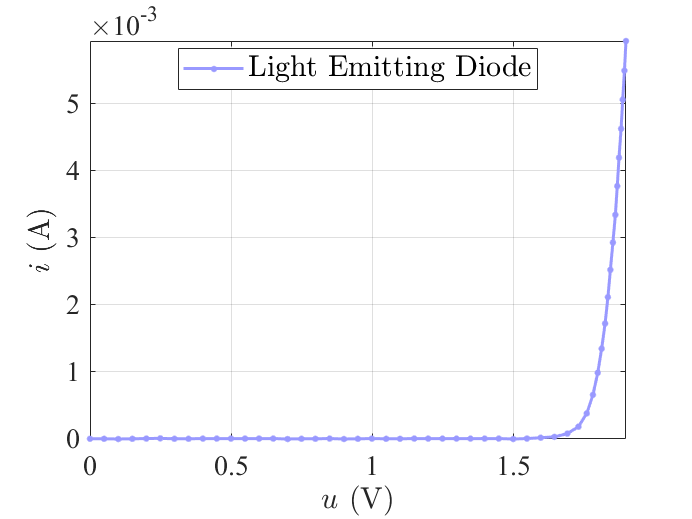

MyExport_pdf

function error = GetError(fun, U, I)
    error = sum( (fun(I) - U).^2 );
end
function error = GetError_fu(fun, u, i)
    error = sum( (fun(u) - i).^2 );
end